# Identifying MR Signals

This tutorial introduces the student to considerations faced by fMRI investigators in distinguishing signals, which we want to measure, from noise, which we don't particularly care to measure. The noise can come from a variety of different areas, which will be discussed in lecture. Among the topics that are covered are:

- Dealing with signal drift 

- Contrast - to - noise ratios (CNR);

- Averaging, spatially and temporally, to enhance CNR

We use data taken from an fMRI scanning session. The session consists of several scans used to localize regions of interest involved in different aspects of vision.

For this week, we're only going to consider a small piece of this data: the time series taken from several voxels located in the subject's right area MT. Area MT (also known as V5 ) is a visual area that is highly responsive to moving stimuli. 

The scan from which the data are taken is an MT localizer scan, in which the subject saw alternating periods of moving and static stimuli. The stimulus was  a series of concentric circles. For 16 seconds, the circles would stay still, then for the next 16 seconds they would move rapidly in and out, then be static, then move, etc.

Each 16-second period is referred to as a **block**. Because there are only two types of blocks in this scan, which alternate, this design is sometimes referred to as an ABAB block design. Each pair of two blocks is called a cycle. The scan consisted of six cycles, each 32 seconds long, for a total of 192 seconds.

('Cycle' refers to the idea that, after a 32-second  cycle the stimulus is in the same state as at the beginning of the cycle. We're interested in finding brain regions whose activation also returns to the same activity level at the same point in a cycle. But this is an aside which we'll explore later.)

- **Class**:     Psych 204A

- **Tutorial**:  Identifying MR Signals

- **Author**:   Rory Sayres/Kalanit Grill-Spector

- **Date**:        04/19/2004

- **Duration**: 45 minutes

- **Author:    **Rory Sayres

## Dealing with drift noise

% Let's load the sample data. As mentioned above, this
% data comes from an MT localizer that lasted 192 seconds,
% and consisted of six cycles of alternating static/motion:
load sampleData;

% the data is contained in a matrix, in which the rows represent time 
% frames and columns represent different voxels. Let's look at the 
% size of our data matrix, using the 'whos' command.
% (An aside: 'who' is a matlab command to show what variables you've
% defined; 'whos' is a more sophisticated command that shows the 
% class of variable, size, and memory taken by each one.)
whos

  Name                      Size                   Bytes  Class                                 Attributes

  CNR                       1x1                        8  double                                          
  CNRdb                     1x1                        8  double                                          
  PRFmodel                  1x44                      88  char                                            
  absFFT                   96x21                   16128  double                                          
  absFFT2                  96x21                   16128  double                                          
  ans                       1x1                        8  matlab.ui.Figure                                
  avgtc                    16x6                      768  double                                          
  blueImg                2064x1552x3            76879872  double                                          
  blueSensor             2064x1552  

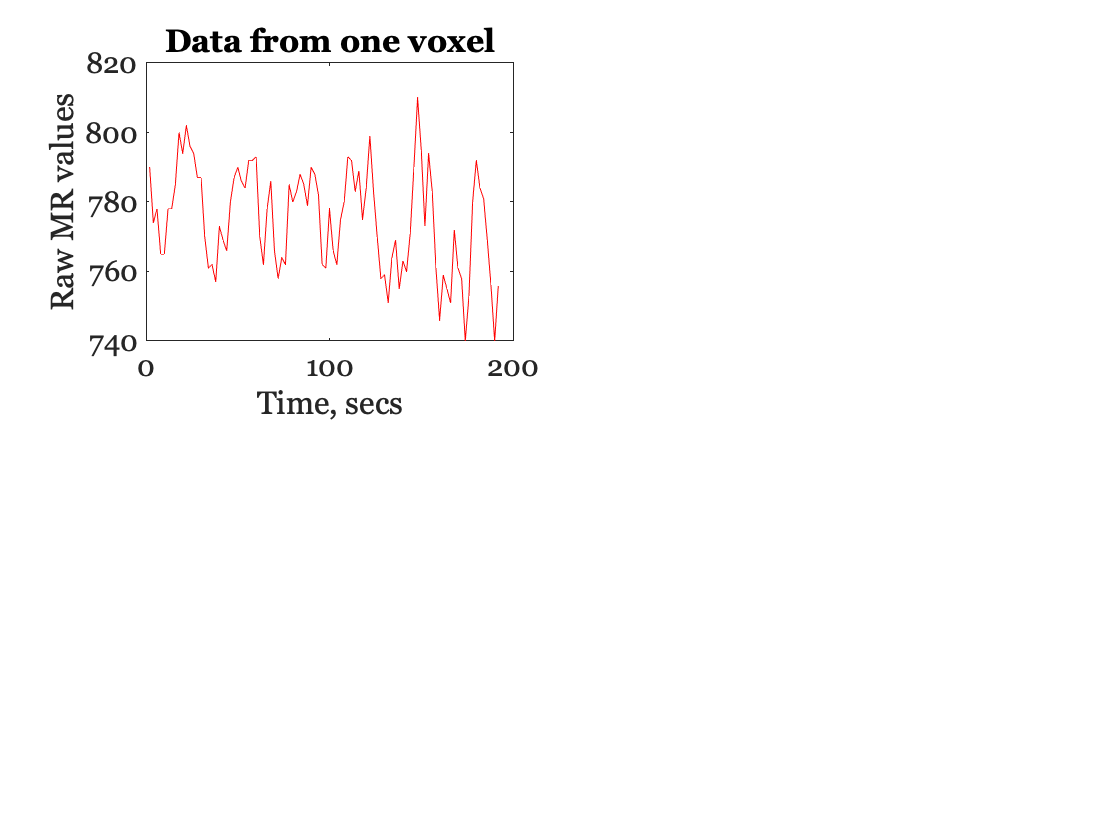


% you should see a table listing an entry 'data': that's our matrix.
% Notice there are 96 rows. This scan had a TR of 2 seconds, so each 
% row represents a 2-second time frame. Each column is the time
% course for the whole scan from a different voxel. Let's 
% plot some of these time courses!
figure; set(gcf,'Name','Data Time Courses');

% First, let's plot the data from one voxel:
subplot(2,2,1); 
t = 2:2:192; % time points for each MR frame
plot(t,data(:,1));
xlabel('Time, secs'); ylabel('Raw MR values');
title('Data from one voxel');

What do you see? First, you may wonder what the y axis represents in this plot. This data is taken straight from the P*.7.mag files that are created at the scanner, after reconstructing the frequency- and phase-encoded signals into an MR image (review the MR Imaging and BasicMR tutorials if you're confused about this). So, these values represent rather arbitrary units, which depend on many different factors that are subject to change from session to session, and even from voxel to voxel. To get a sense of how the raw signal can vary, let's plot all 21 voxels in this sample data:

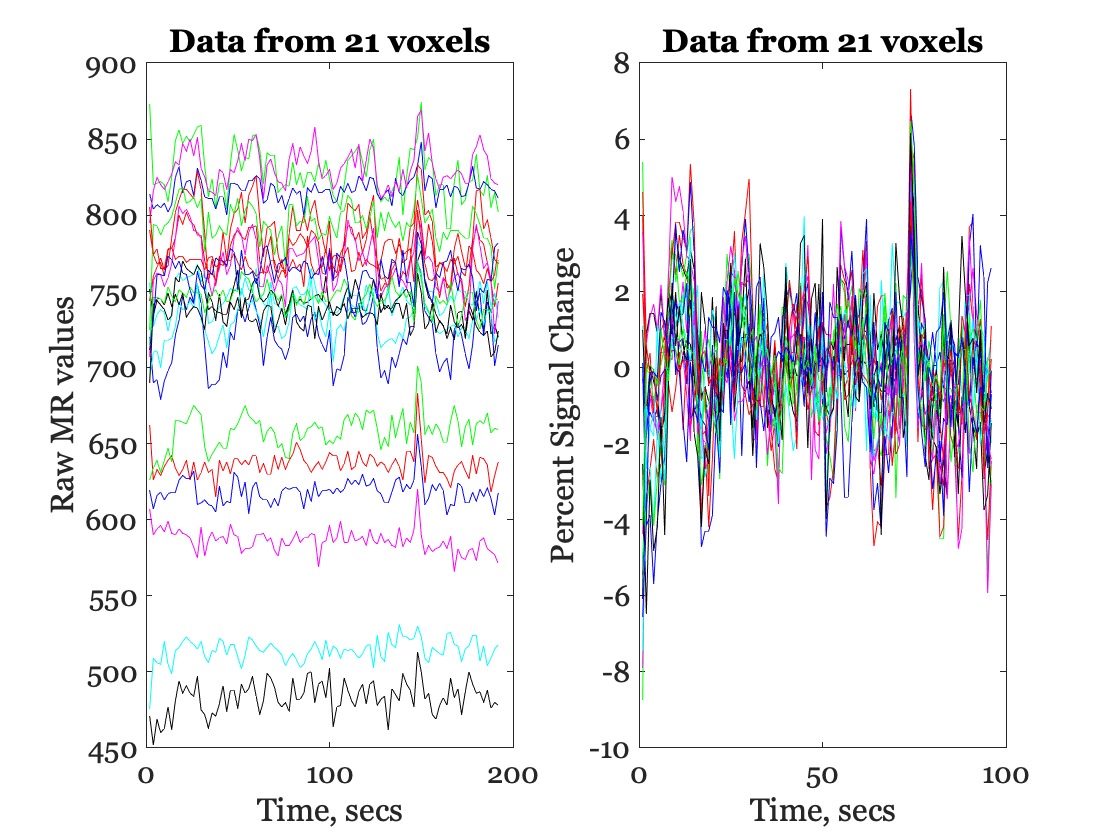

figure;  set(gcf,'Name','Data Time Courses');
subplot(1,2,1);
cla;
plot(t,data);
xlabel('Time, secs'); ylabel('Raw MR values');
title('Data from 21 voxels');

% notice how the time courses from different voxels
% can be shifted by very large amounts from one another?
% what we're interested in is the variations in the 
% overall signal that are caused by our varying 
% experimental conditions. 
%
% There are many ways to account 
% for these shifts; one of the simplest ways to do this 
% is to convert to a percent signal change. We can do 
% this by dividing the time course of each voxel 
% by the mean intensity for that voxel:
dc = mean(data); % dc is our estimate for the baseline offset
data = data ./ (ones(size(data,1),1)*dc);

% now, the mean of each time course is 1;
% we'll subtract this away to set the mean to 
% 0 -- meaning zero signal change away from 
% the mean MR intensity:
data = data - 1;

% and to get percent, we multiply by 100:
data = 100 .* data;

% let's look at the time courses now:
subplot(1,2,2);
cla;
plot(data);
xlabel('Time, secs'); ylabel('Percent Signal Change');
title('Data from 21 voxels');


% note that the time courses are much more comparable
% now. 
%
% (Also, an aside: we set 0 percent signal to mean
% no deviation from the mean for the whole time 
% course for that voxel. There are other ways 
% to do this; for instance, many analyses will
% set 0 percent signal to mean the mean value of 
% a particular null or baseline condition to which
% other conditions are compared. We could do that here,
% treating the non-moving stimulus condition as 
% a baseline and comparing it to motion -- but we'll
% keep things simpler for now.) 

% Now that we've gotten the difference between raw
% signals and percent signal change, we can go back 
% to looking at the time series from one voxel. Let's 
% re-plot this voxel as percent signal:
figure;  subplot(2,2,2);
cla;
plot(t,data(:,1));
xlabel('Time, secs'); ylabel('Percent Signal Change');
title('Data from one voxel');


### Signal drift

You may have noted,  maybe before anything else, that the signal cycles up and down six times. We're slowly getting to that. But first, you may notice something else that may be  troubling: the signal 'droops' towards the end of the scan. This change over time is known as **signal drift**, and is caused by the scanner hardware, rather than the brain itself. 

Therefore, it's something to take into account when identifying signals.

There are many strategies to deal with signal drift. We'll talk about a few. First, there's a linear trend removal: we assume that the drift can be described by a simple line, and subtract our estimate of that drift. 

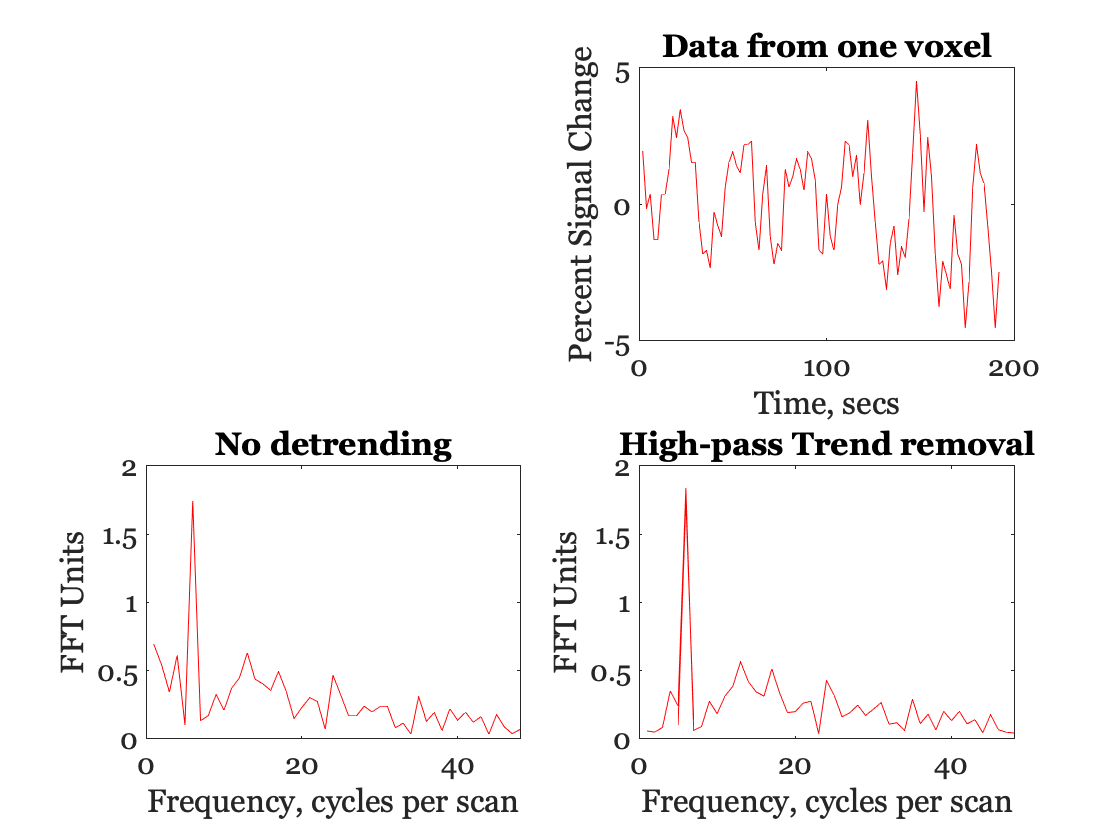

% We'll use the function detrendTSeries to 
% do this (edit detrendTSeries to see how
% the model is implemented):
detrendedData1 = detrendTSeries(data,-1); % -1 means linear trend removal

subplot(2,2,3); 
plot(t,detrendedData1(:,1));
xlabel('Time, secs'); ylabel('Percent Signal Change');
title('Linear Trend removal');

% notice how the drooping is gone? 

% There are other, more sophisticated detrending
% options that have come up to deal with baseline
% drift, which doesn't always drift linearly. One
% form of drift which sometimes occurs is slow 
% baseline drift: the drift goes up and down at
% a very slow rate, for instance one cycle per minute.
% We can also try removing this estimated drift. 
% Note that this is a form of high-pass filter.
detrendedData2 = detrendTSeries(data,1,16); 

% the 1 means do a low-frequency drift removal,
% and the 16 gives the period of the estimated
% drift.
subplot(2,2,4);
plot(t,detrendedData2(:,1));
xlabel('Time, secs'); ylabel('Percent Signal Change');
title('High-pass Trend removal');

% Notice this doesn't do much more than linear trend
% removal for this case. (It can help for other 
% experimental designs and scans, though.)

% Now, we plot the Fourier spectrum of 
% different frequency energies in the data, to give a
% sense of where the low-frequency drift is
% we take the absolute value of the fft of the data
absFFT = 2*abs(fft(data)) / length(data); 
nFrames = size(data,1); % the # of temporal frames: 92
xfreq = 1:nFrames/2; % the different frequencies we'll plot
subplot(2,2,3);
plot(xfreq,absFFT(2:(nFrames/2)+1));
hold on, plot(xfreq(5:7),absFFT(6:8),'r'); % stimulus-driven signal
xlabel('Frequency, cycles per scan')
ylabel('FFT Units');
title('No detrending')

absFFT2 = 2*abs(fft(detrendedData2)) / length(detrendedData2); 
subplot(2,2,4);
plot(xfreq,absFFT2(2:(nFrames/2)+1));
hold on, plot(xfreq(5:7),absFFT(6:8),'r'); % stimulus-driven signal
xlabel('Frequency, cycles per scan')
ylabel('FFT Units');
title('High-pass Trend removal')

## Question 1

(a) Where did the fourier transform change as a result of the trend removal and why?

(b) Why would this help signal drift, but not, e.g. pulse / respiratory artifacts?

(c) Why, for a 192-second scan, would six cycles, but not three cycles or forty cycles, be useful for experimental design? Can you think of any potential drawbacks?

**(Extra Credit)** Try using detrendTSeries to perform quadratic detrending on the data (assume the trend is a quadratic function), and compare it to the other two types of detrending.

## Contrast-to-Noise Ratios (CNR)

Now we move on to the periodicities we've noted in the data. We note that the main fluctuation occurs six times over the course, the same as the number of times the stimulus varied between static and moving. We believe this fluctuation represents the motion-selective signal from MT.

However, you may recall generating predicted hemodynamic responses during the linear systems tutorial -- those predicted responses were much cleaner than what we see here. There's a certain amount of noise. This can come from many sources, including both the instrumentation and the brain itself, which we discuss more fully in class.

Before we can come up with plans of dealing with this noise, we first want a quantitative way to describe how much noise there is relative to the signal we want to measure. We'll use the well-known measurement of signal-to-noise ratio, or in this case, contrast-to-noise ratio (CNR). (Note that the Huettel book calls this quantity functional SNR; it's also referred to as functional CRN or dynamic CNR).

As its name suggests, CNR is a ratio, measuring the size of the signal we measure relative to the variance in its measurement. 

% First, let's make some plots to get
% some sense of the variance. 
figure;  set(gcf,'Name','Contrast to Noise');

% We'll take the time course from the first voxel, after
% detrending. We'll plot the data from each cycle
% separately:
voxtc = detrendedData2(:,1);

numCycles = 6; 
framesPerCycle = 16;
voxtc = reshape(voxtc,[framesPerCycle numCycles]);

subplot(1,2,1);
plot(repmat(2:2:32,[numCycles 1])',voxtc);
xlabel('Time during cycle, sec'); ylabel('Percent Signal Change');
title('Indiviudal Cycles')
axis tight

% you can see there is variance between different trials.
% A frequent way to display this is by plotting standard
% deviations or standard errors over the mean time course:
subplot(1,2,2);
hold on
patch([16 16 32 32],[-5 -4.7 -4.7 -5],'k');
errorbar(2:2:32,mean(voxtc'),std(voxtc'));
xlabel('Time during cycle, sec'); ylabel('Percent Signal Change');
title('Mean Cycle + Std Dev')
axis tight
hold off

% I've added a black bar at the bottom indicating when the motion
% stimulus was shown. Now, to calculate CNR, we want to measure the
% difference in signal during this time relative to the baseline
% condition (when the static stimulus was shown), and divide
% by the standard deviation during the baseline condition:
staticFrames = 1:8; 
motionFrames = 9:16;
staticValues = voxtc(staticFrames,:);
motionValues = voxtc(motionFrames,:);

signal = mean(motionValues(:)) - mean(staticValues(:));
noise = std(staticValues(:));

CNR = signal/noise

CNR = 1.4305


text(3,3,sprintf('CNR: %2.2f',CNR));

% another way to express the signal to noise is in decibels,
% which are defined as 20 * the log base 10 of the ratio:
CNRdb = 20 * log10(CNR)

CNRdb = 3.1096

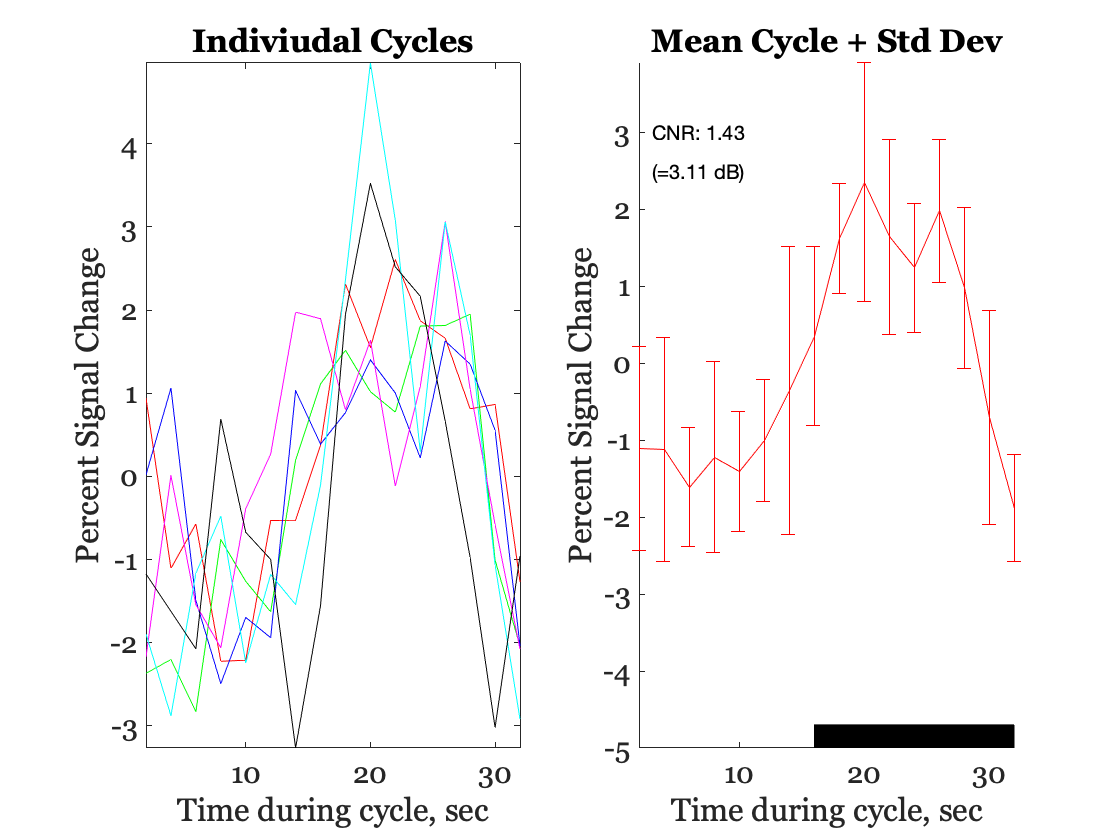


text(3,2.5,sprintf('(=%2.2f dB)',CNRdb));


% (and yes, these are the same decibels as used in sound --
% decibels are a log scale of the intensity of a sound.)

% (Note also that right now we're including the transition
% times between blocks when the hemodynamic response rises
% and falls. If we'd calculated only during times we'd 
% consider the signal to have reached steady state, the 
% CNR would be higher.)

## Simulations

To get a sense of how noise affects the signal, let's take some fake data and add varying levels of noise to it. 

% We'll construct a pulse which specifies when the motion
% signal is on
cycle = [zeros(1,8) ones(1,8)];
pulse = repmat(cycle,[1 numCycles]);

% And we'll take a gamma function hrf:
hrf = heeger_hrf(2:2:16);

% Let's plot both the function and the hrf:
figure;  set(gcf,'Name','Fake data set with noise');
subplot(5,2,1); 
plot(t,pulse,'k');
axis([0 200 -2 2]);
xlabel('Time, sec'); ylabel('Motion');
title('Stimulus');

subplot(5,2,2);
plot(2:2:16,hrf,'r');
axis([0 18 -0.4 0.4]);
xlabel('Time, sec'); ylabel('% Signal');
title('Ideal HRF');


Now we convolve to get an estimate of the ideal response to the stimulus, with no noise, and calculate the CNR (we'll use the calcCNR function, which does the same calculation we did above):

y0 = conv(pulse,hrf);

CNR = calcCNR(y0(:,4:99));

subplot(3,2,3);
plot(2:2:2*length(y0),y0);
axis([0 210 -0.4 0.8]);
xlabel('Time, sec'); ylabel('% Signal');
title('Ideal Signal');
text(5,-0.2,sprintf('CNR: %2.2f dB',CNR));


(Note that the zero point for this data represents the mean value during the baseline period, rather than the overall mean, as was discussed earlier. Always remember to check what the experiments set as the zero point when reading fMRI studies!)

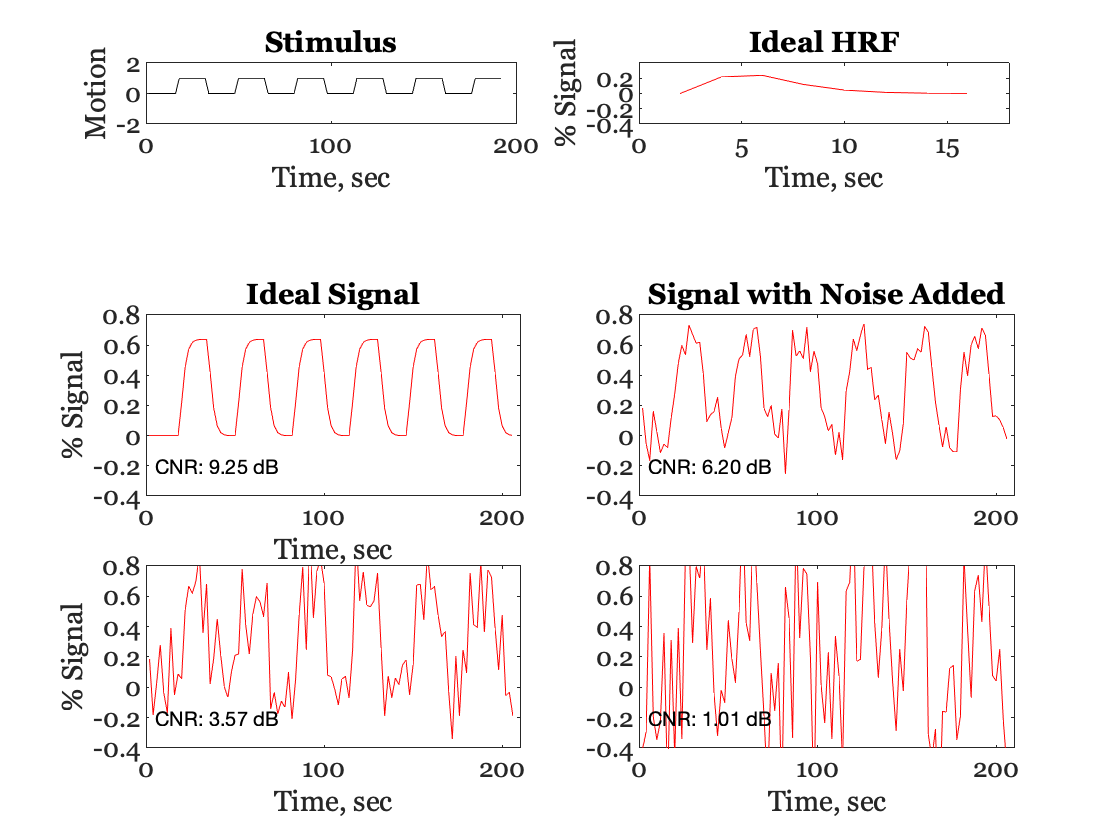

% Now let's add varying levels of noise and 
% calculate the CNR in each case:
noiseLevels = [.1 .2 .5];
for i = 1:3
    noise = noiseLevels(i) * randn(size(y0));
    y1 = y0 + noise;

    CNR = calcCNR(y1(:,4:99));
    
    subplot(3,2,i+3);
	plot(2:2:2*length(y1),y1);
	axis([0 210 -0.4 0.8]);
    if i > 1    xlabel('Time, sec');    end
    if i==2     ylabel('% Signal');     end
    if i==1	    title('Signal with Noise Added');   end
	text(5,-0.2,sprintf('CNR: %2.2f dB',CNR));
end

## QUESTION 2

(a) In the 4th subplot, you'll note that the CNR, as expressed in decibels, is negative. What does this signify?

(b) What is the difference between this CNR measure, and signal-to-hoise as described in the Huettel book?

## Averaging, spatially and temporally, to enhance CNR

Now we can describe how well we've identified a signal relative to noise -- now how can we reduce the noise? 

There are many different approaches being taken for this. We'll just describe one that is commonly used -- averaging the data, both spatially across voxels and temporally across scans, to achieve a higher contrast-to-noise ratio.

First, let's average across voxels. We've already looked at the differences across time courses from different voxels in our sample data. Let's look at them again, separately for each voxel, for the first ten voxels. For each time course we'll calculate the CNR for that voxel alone:

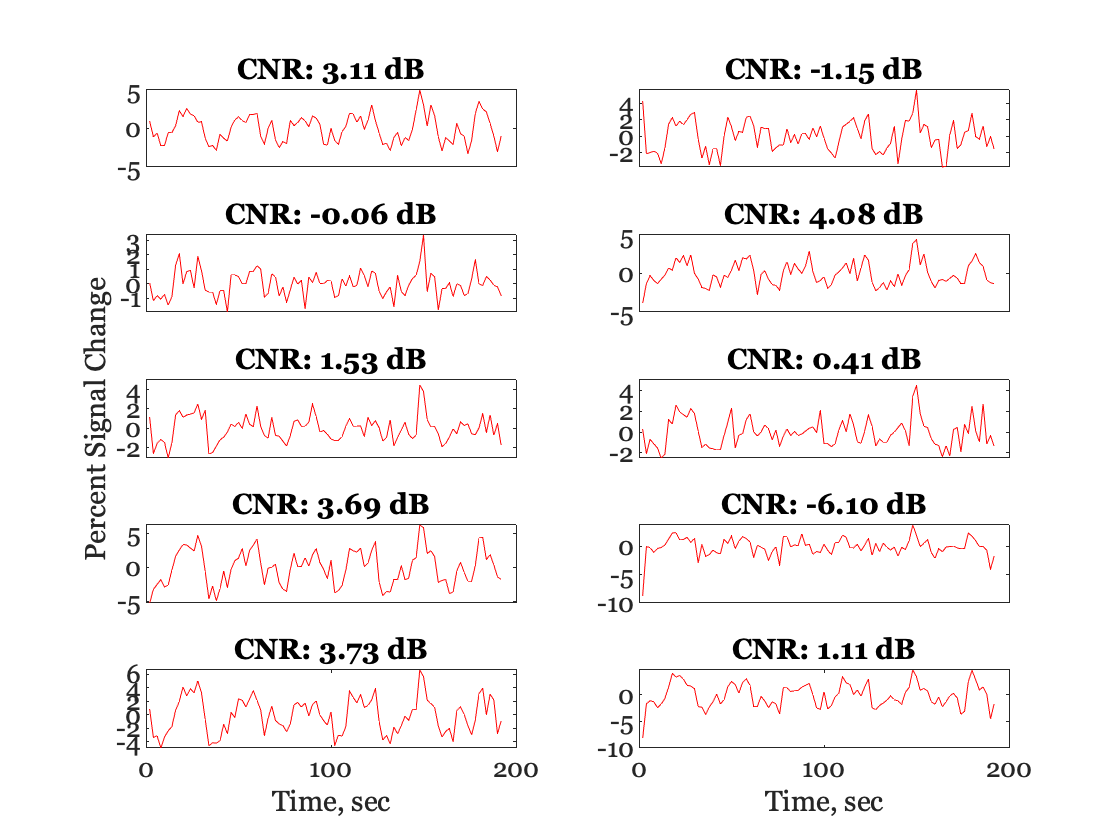

figure;  set(gcf,'Name','Single Voxel Time Courses');
for i = 1:10
    subplot(5,2,i);
    plot(t,detrendedData2(:,i));
    set(gca,'XTick',[]);
    
    % calculate the CNR for this voxel
    voxtc = detrendedData2(:,i);
    CNRdb = calcCNR(voxtc);
    title(sprintf('CNR: %2.2f dB',CNRdb));

    
    if i==5             ylabel('Percent Signal Change');    end
    if i==9 | i==10     
        xlabel('Time, sec');                
        set(gca,'XTick',[0 100 200]);
    end
end

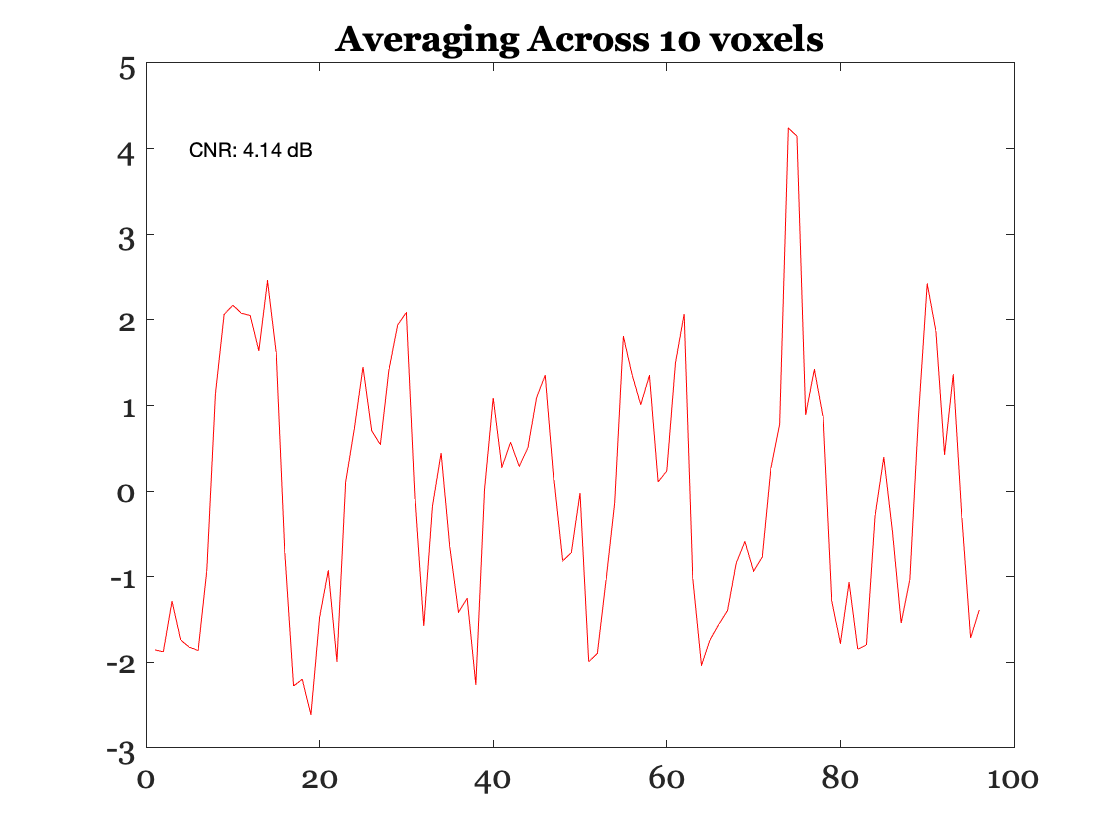


% Now we'll average across these ten voxels, and compute the CNR:
figure;  set(gcf,'Name','Averaging Across Voxels');
% subplot(2,1,1);
avgtc = mean(detrendedData2(:,1:10)');
plot(avgtc);
avgtc = reshape(avgtc,[framesPerCycle numCycles]);

% We'll calculate the CNR of this average time course:
staticValues = avgtc(staticFrames,:);
motionValues = avgtc(motionFrames,:);
signal = mean(motionValues(:)) - mean(staticValues(:));
noise = std(staticValues(:));
CNRdb = 20 * log10(signal/noise);
text(5,4,sprintf('CNR: %2.2f dB',CNRdb));

title('Averaging Across 10 voxels')

The **temporal averaging** can be done across different scans of the same type, which unfortunately isn't available for this data set. But we can view the repeated cycles as being the same idea -- increasing the number of observations, so as to improve our estimate of the signal relative to the noise.

## QUESTION 3

(a) Think of an instance in which spatial averaging would cause a reduction in the CNR. 

(b) Think of an instance in which temporal averaging would cause a reduction in the CNR. 

**END**